% Output tiff images from matrix for visualization written by NY
clear all;
close all;
clc;

CompNum = 40;

Initial = 'NY';
Animal = 'cam228';
Date = '221118';
Block = 1;
Key = 'min';
working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\';

% for visualizing images after PCA/ICA
cd([working_directory Date filesep Initial '_' Animal filesep 'ICA\ICA_40']);
load([Initial '_' Animal '_RecICA_' num2str(CompNum) '_' Key],'RecICA_Temp','-mat');
mkdir(['RecICA_out_' Key]);

max(max(RecICA_Temp{1}))

ans = 0.2295

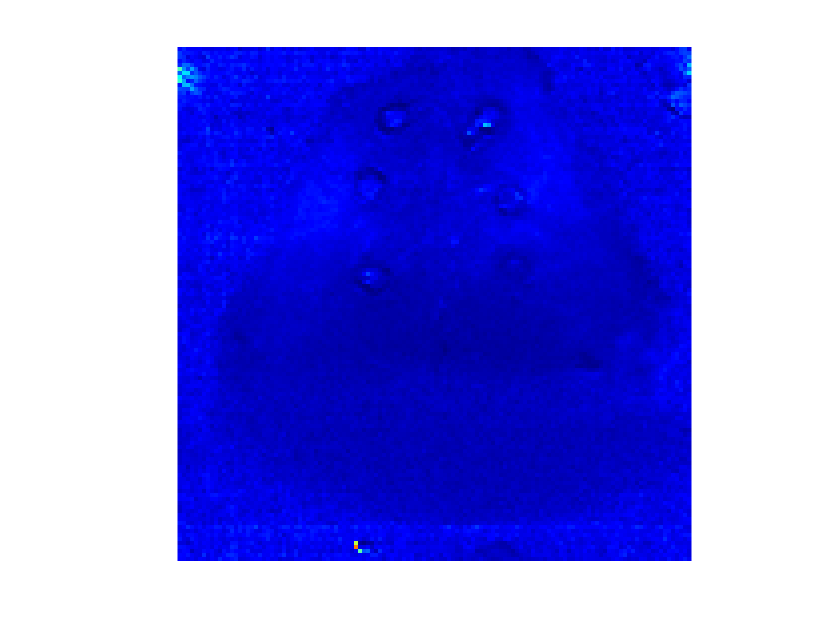

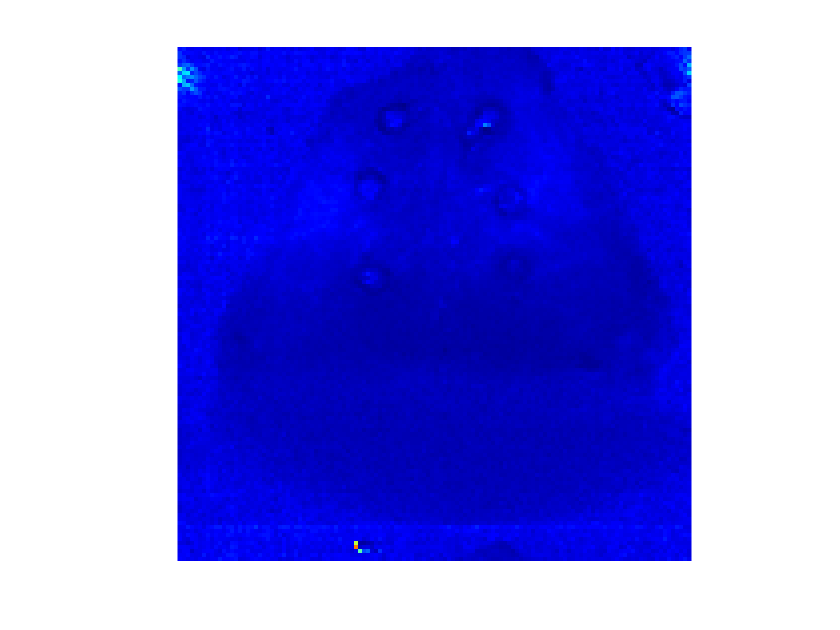

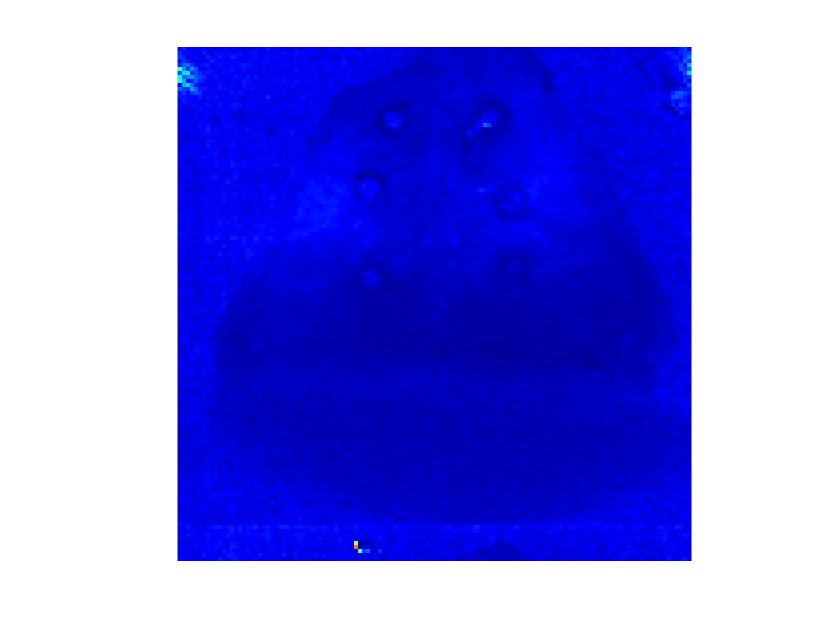

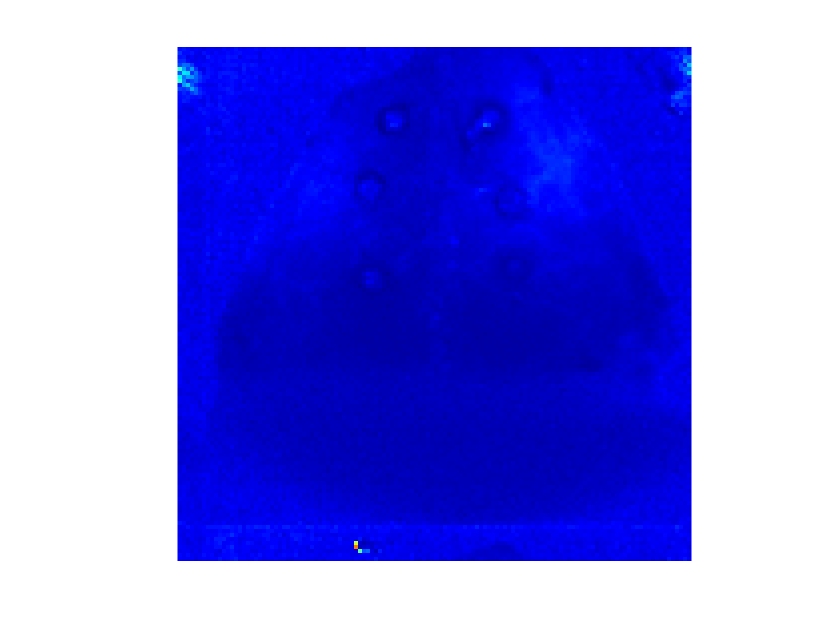

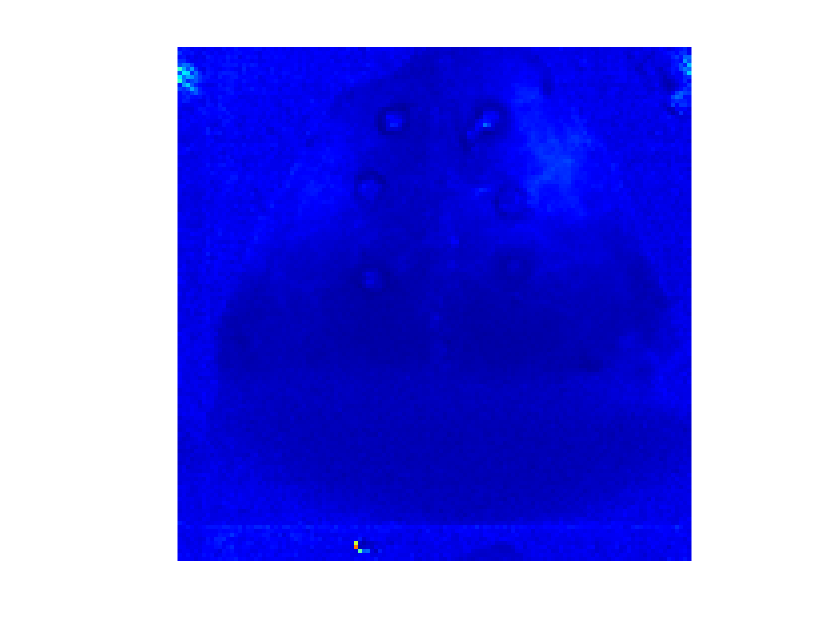

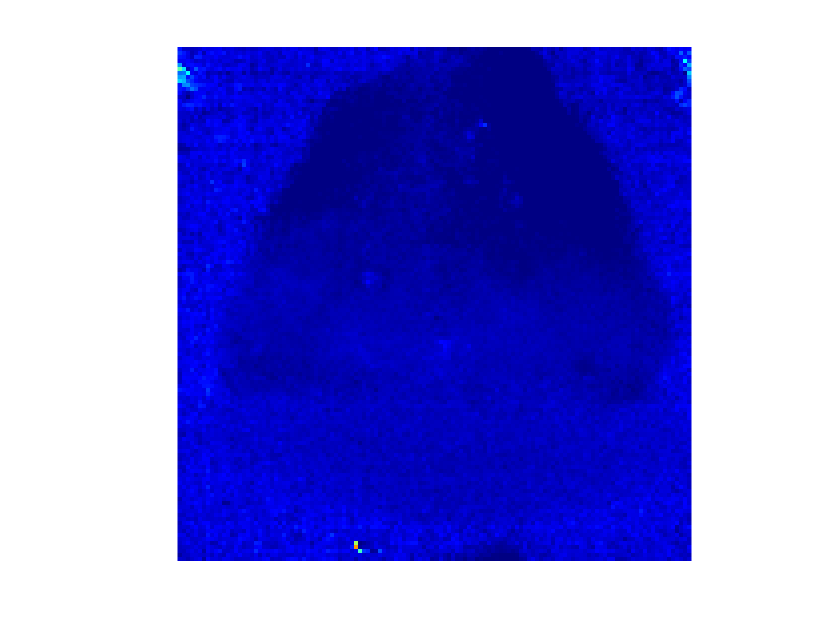

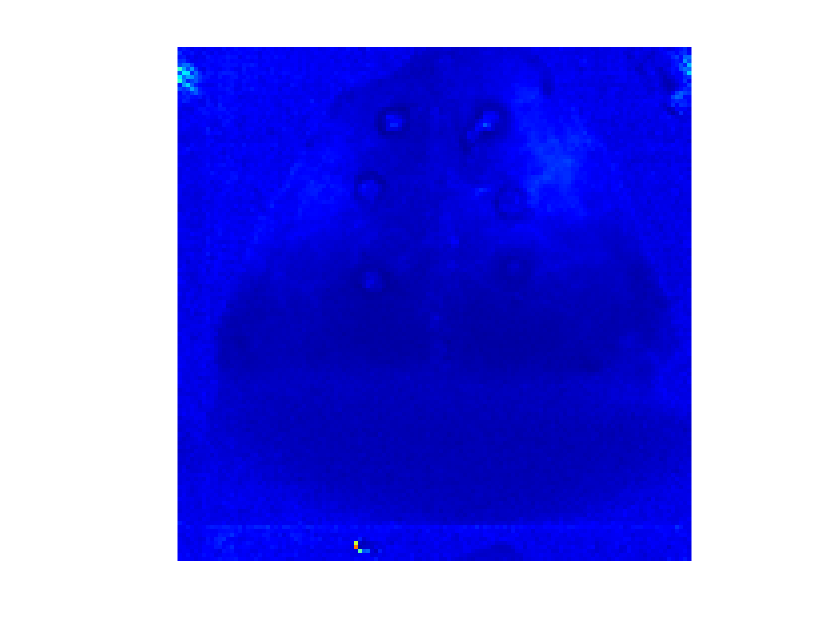

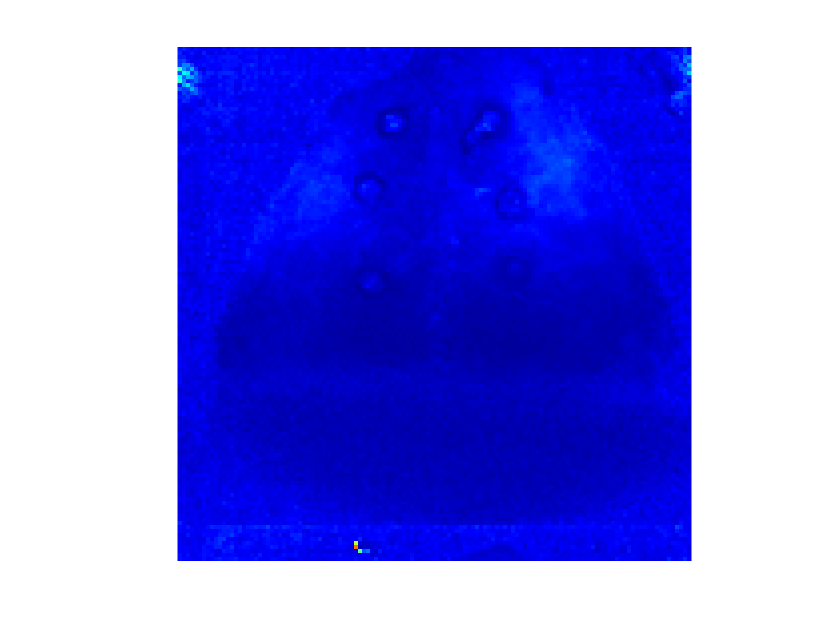

clims = [0 0.3]; % adjust by using max(max(RecICA_Temp{1})) (upper limit)

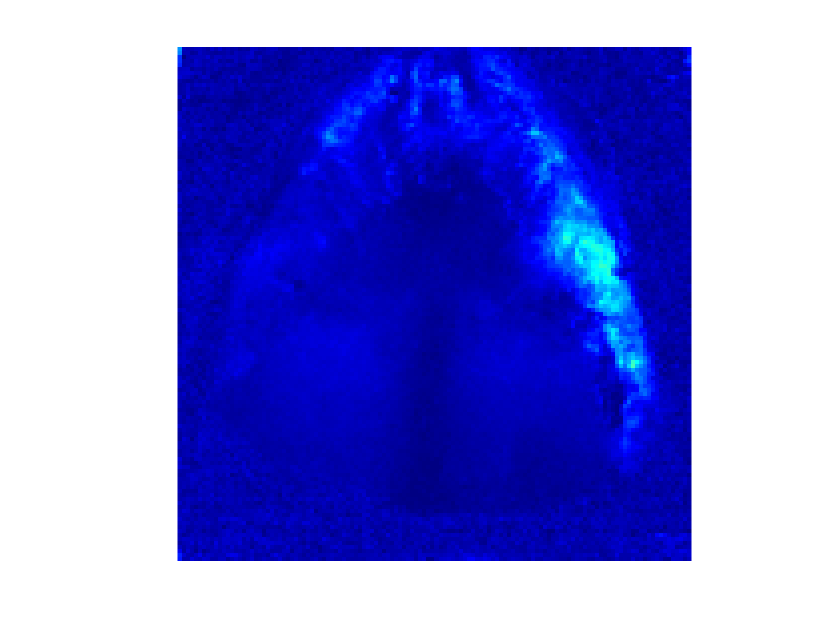

for i = 1:size(RecICA_Temp{Block},2)
    figure;
    set(gcf,'color','w');
    image = RecICA_Temp{Block}(:,i);
    imagesc(reshape(image,[128 128]),clims);
    colormap jet;
    axis square;
    axis off;
    filename = ['RecICA_out_' Key filesep 'RecICA_' num2str(Block) '_', num2str(i), '.tif'];

    saveas(gcf,filename);
end
close all

% figure;
% clims = [0 0.8];
% image = RecICA_Temp{1}(:,1);
% imagesc(reshape(image,[128 128]),clims);
% colormap jet;
% axis square;
% axis off;

% close all